# PROBLEM SET 01

## Exercise 2

% Implement given matrix
clc;clear;

A_c = [-5 -2.7 ; -3.1 1.5];
B_c = [4 2.1 ; 1.1 3];

C_c = [1 1];
D_c = [0 0];

### Exercise 2.a

Using Euler first order discretization we get

Ts = 0.5;
Tend = 5;
x0 = [0 , 0];

xEuler(1,:) = x0
% Euler first order
for i = 1 : Tend/Ts
    xEuler(i+1,:) = xEuler(i,:) + Ts*xEuler(); 
end


### Exercise 2.b

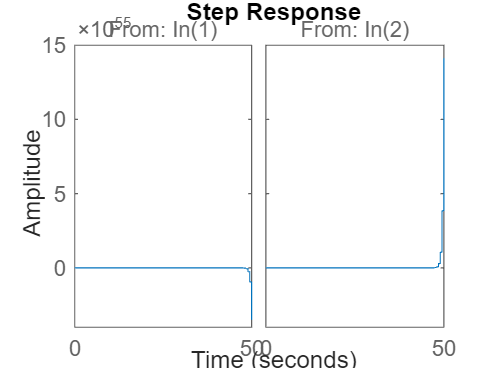

A_exact = expm(A_c * Ts);

sysc = ss(A_c , B_c , C_c ,D_c);
sysd = c2d(sysc , Ts);

step(sysd)

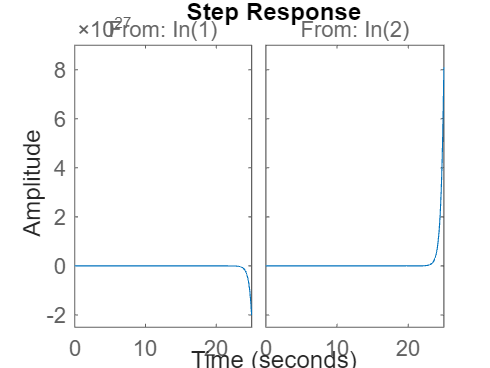

step(sysc)